% generate figure S1
% dependence: initRSG2prior, v2struct, applytofig

### set up

S=initRSG2prior;
v2struct(S); % behDir animalNm nAnimal

### main loop

H


FigS1A


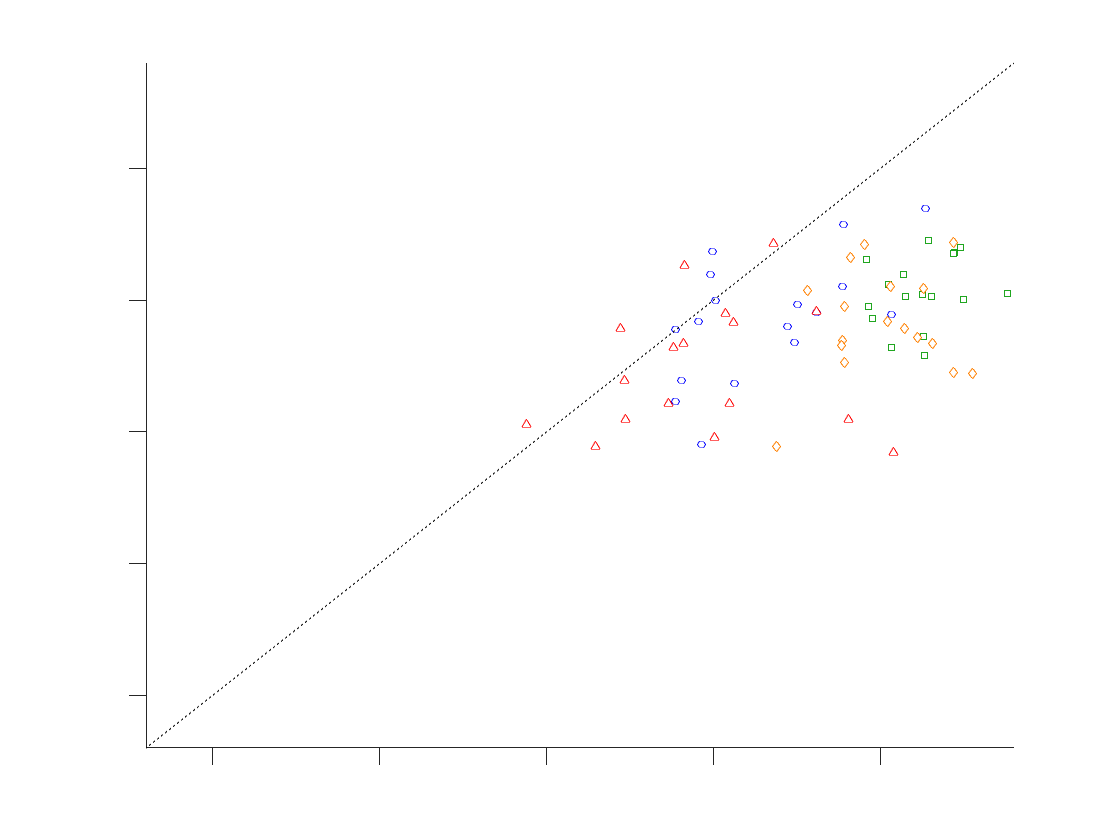

# trials: 309, 85
FigS1B


FigS1C


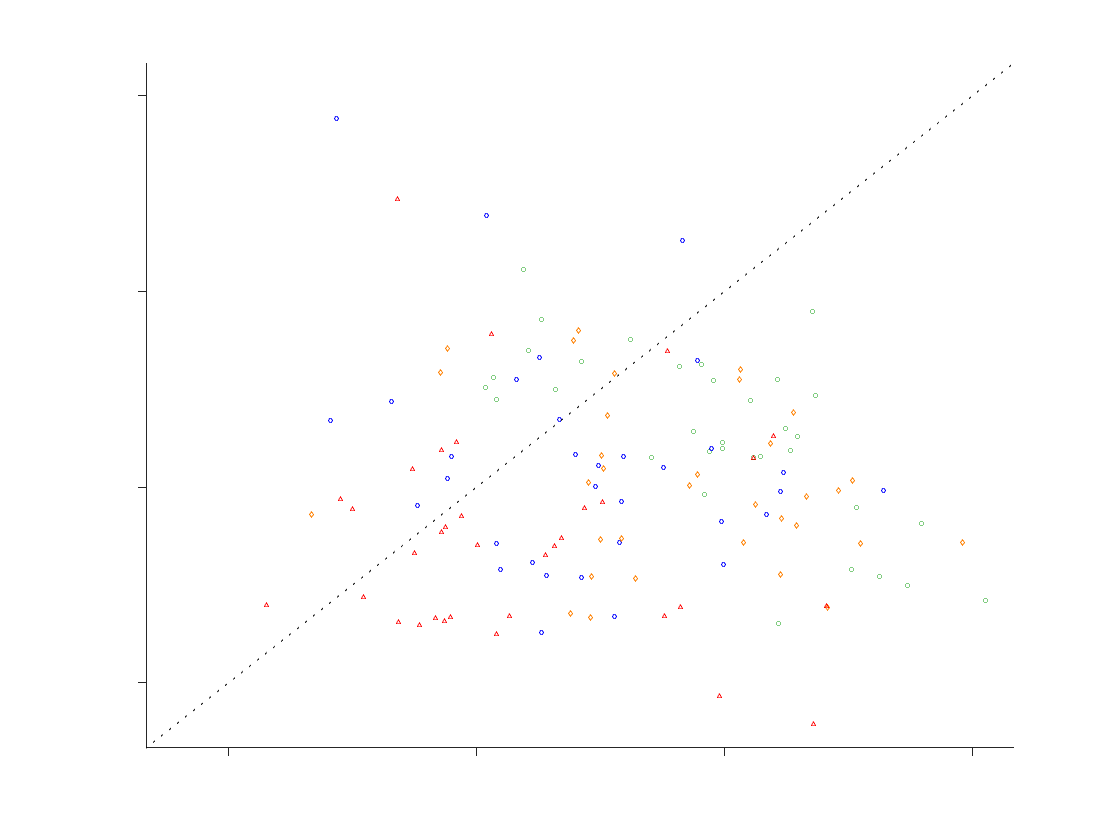

FigS1D


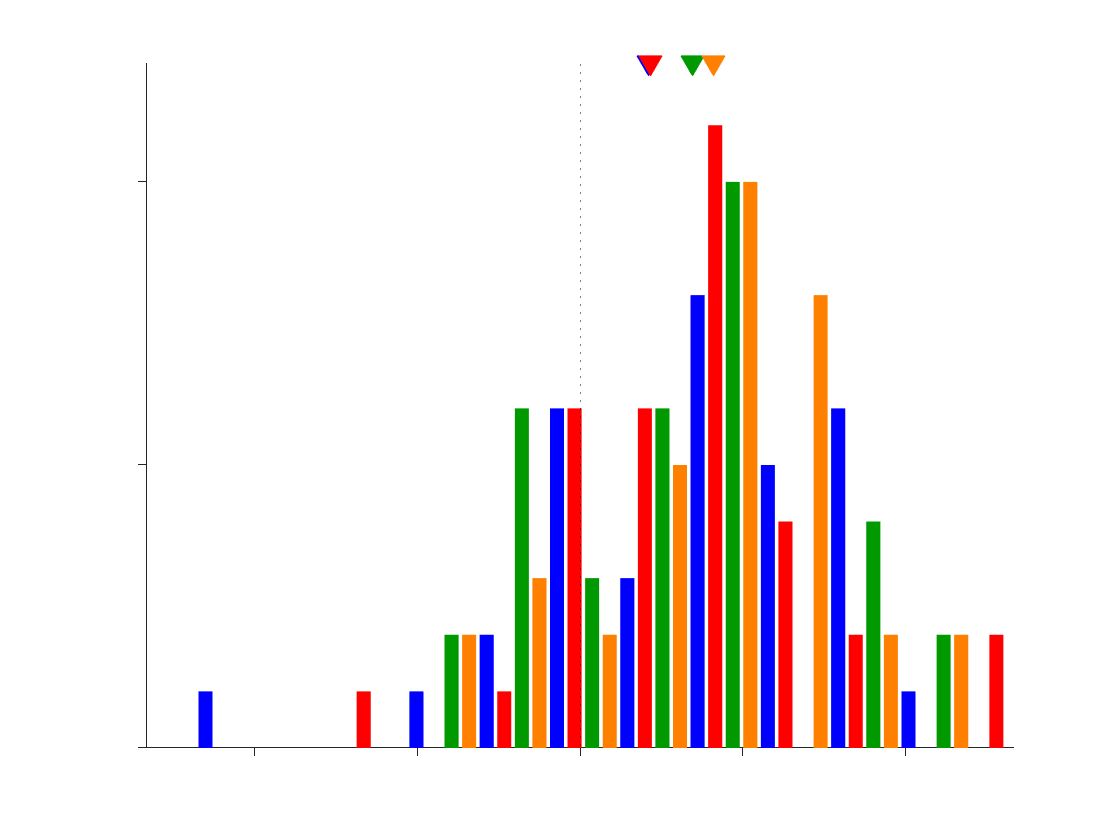

FigS1F
H_20190315_RSGadapt.mat
     1

   660

% outlier: 7.377
   705

% outlier: 8.4577
   750

% outlier: 7.0652
   795

% outlier: 6.7183
   840

% outlier: 5.2023
   885

% outlier: 7.5949
   930

% outlier: 6.3401
   975

% outlier: 7.6316
        1020

% outlier: 6.8966


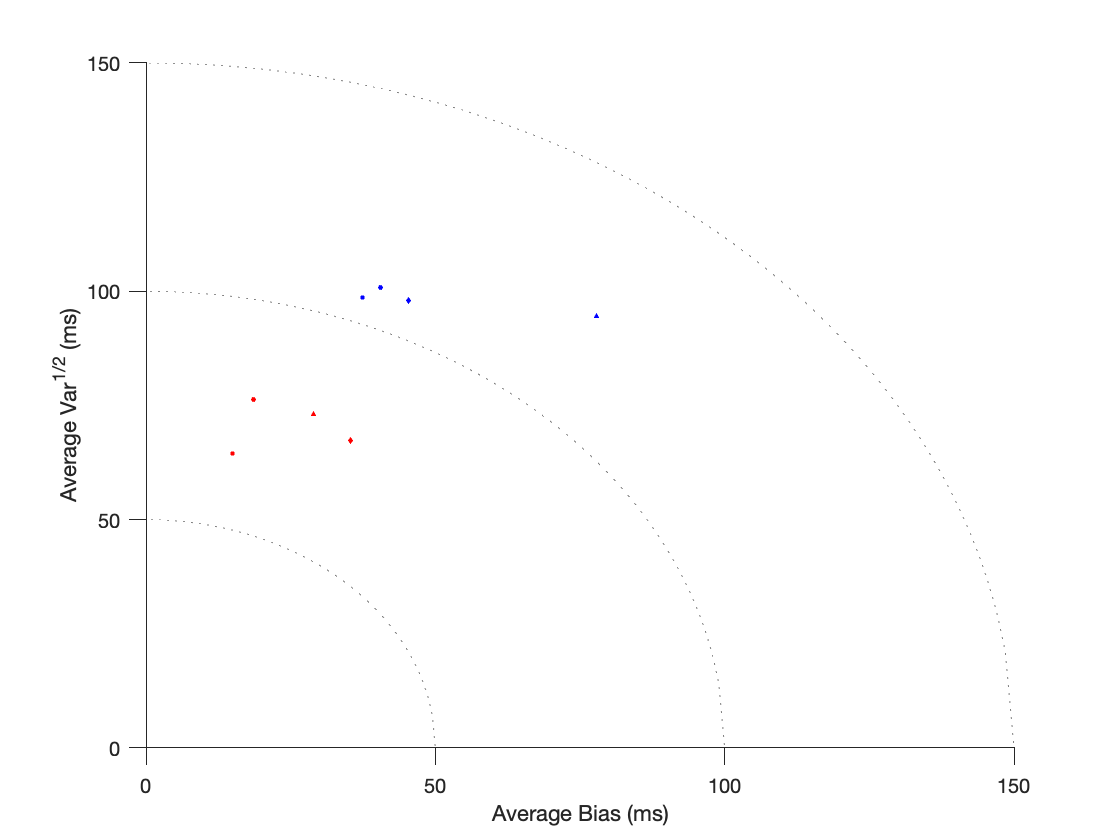

intercept: 1.035700e+02 (p=9.654410e-04), slope: 8.778611e-01 (p=1.861535e-09)


# trials: 3130


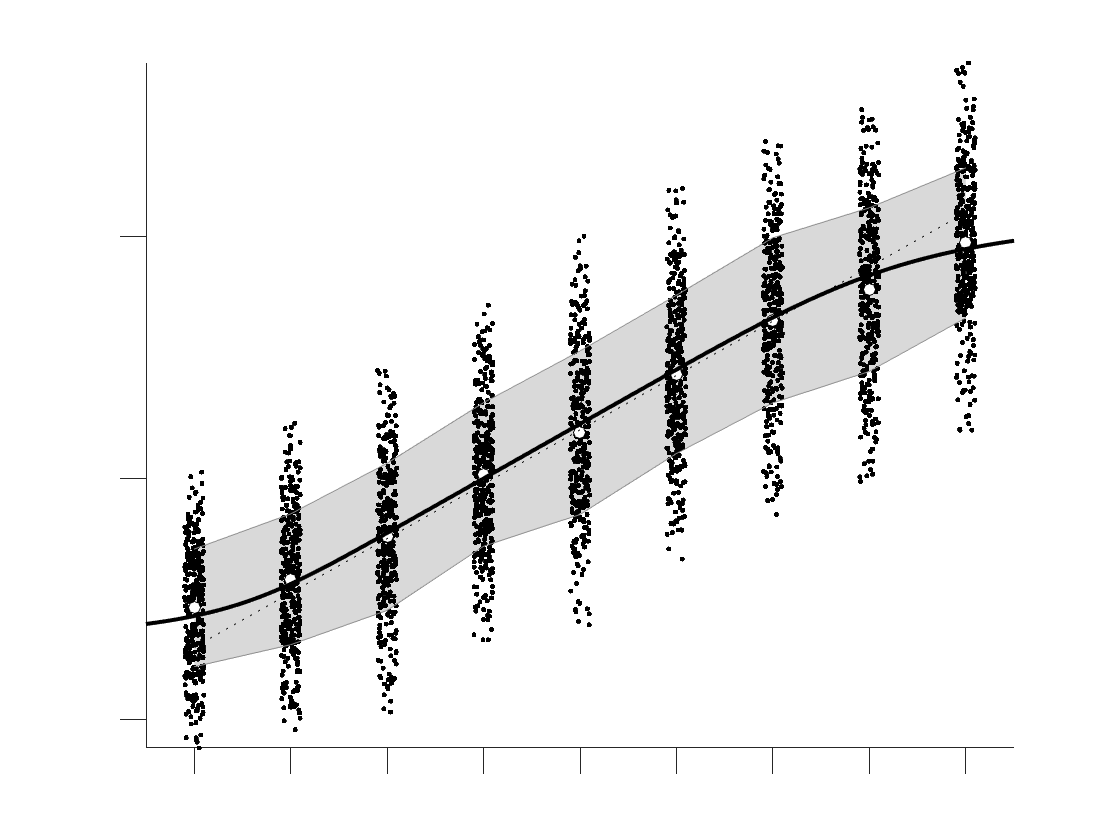

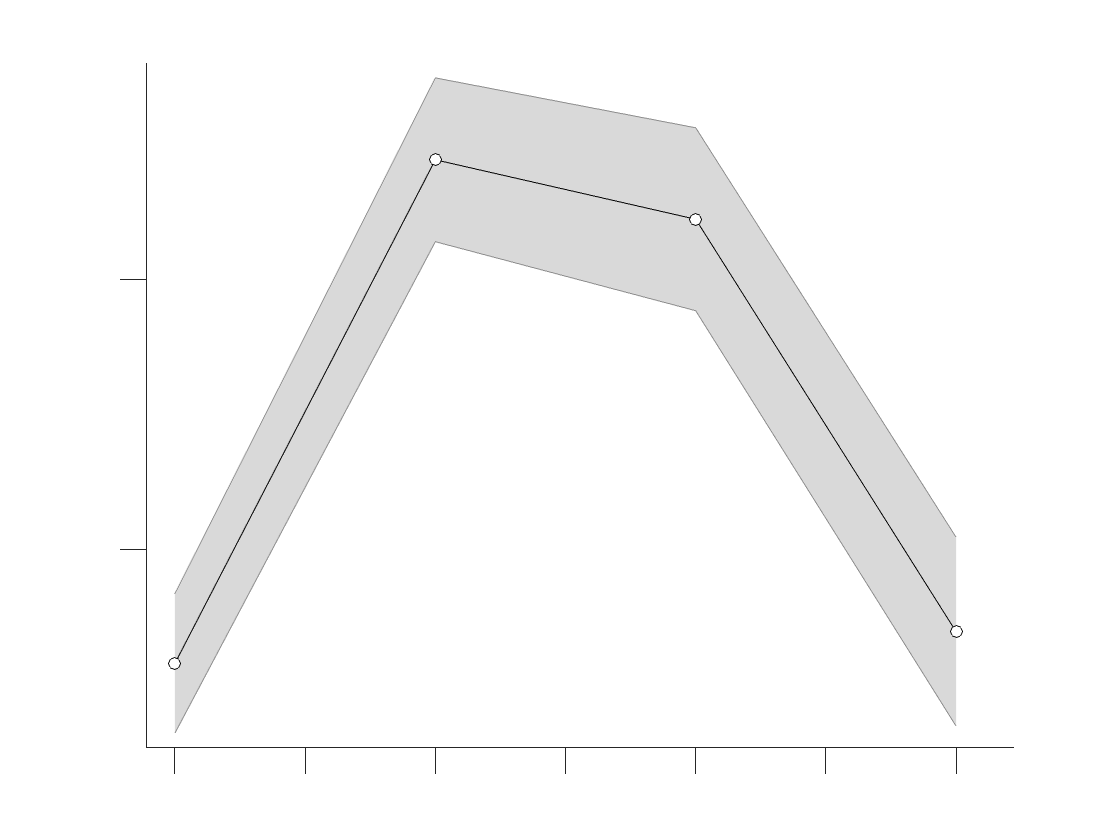

G


FigS1A


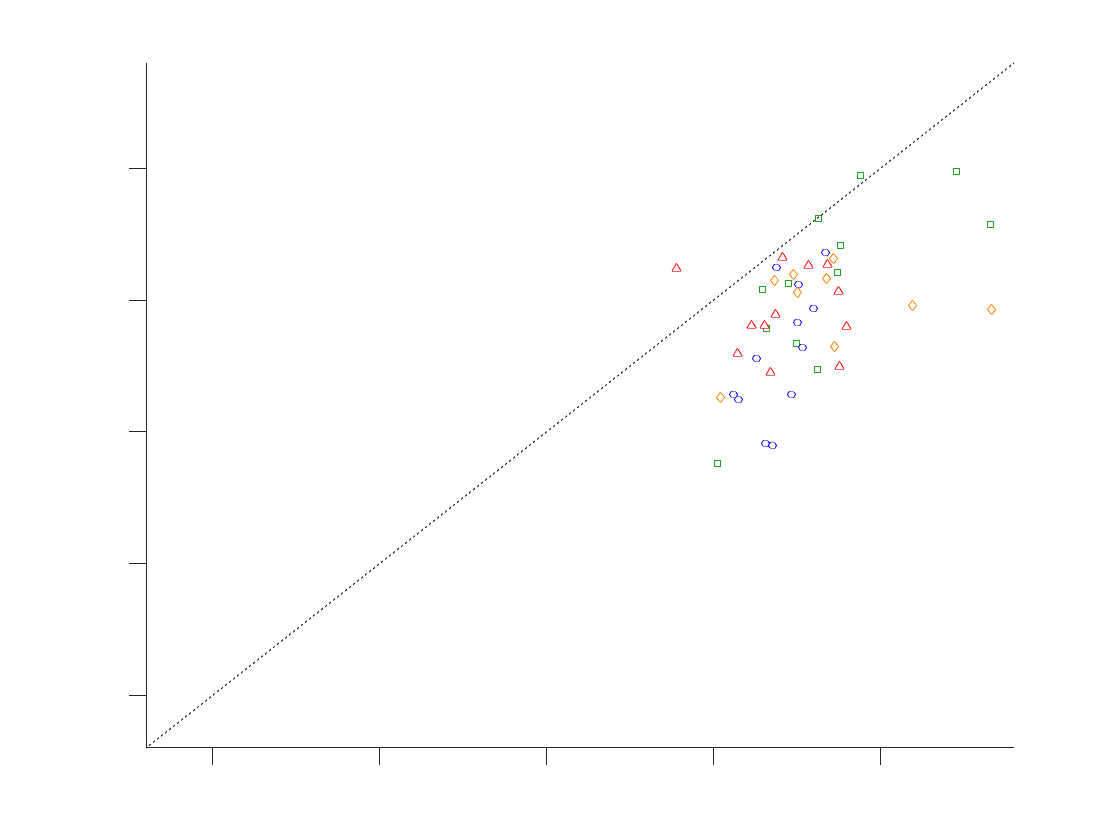

# trials: 511, 139
FigS1B


FigS1C


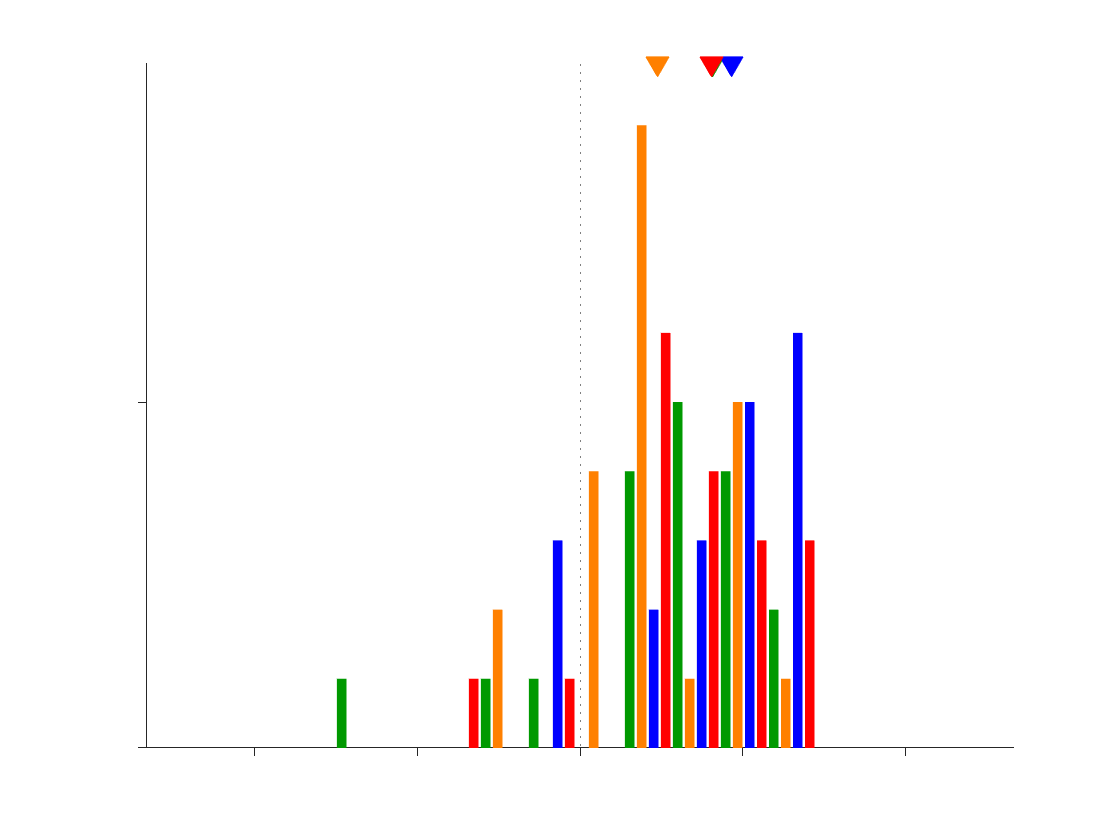

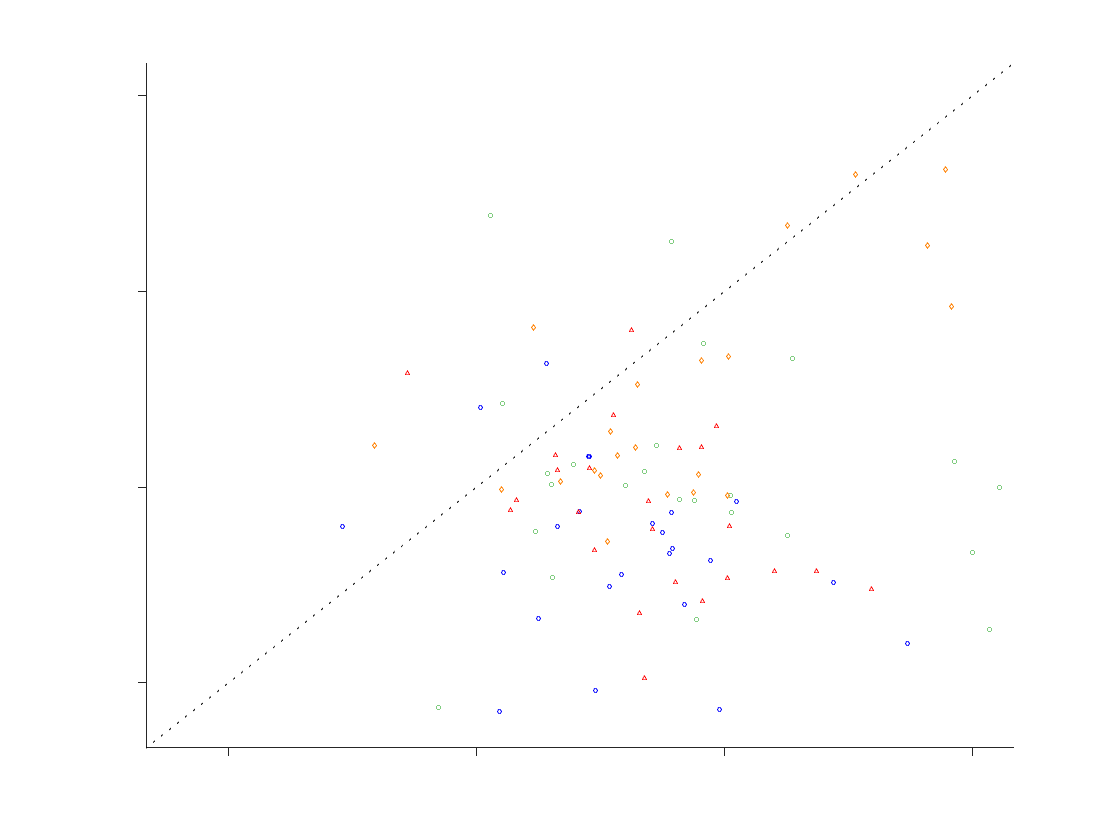

FigS1D


FigS1F
G_20190322_RSGadapt.mat
     1

   660

% outlier: 4.6798
   705

% outlier: 2.9973
   750

% outlier: 4.8101
   795

% outlier: 6.0686
   840

% outlier: 5.3191
   885

% outlier: 5.1948
   930

% outlier: 8.1731
   975

% outlier: 9.8726
        1020

% outlier: 13.3136


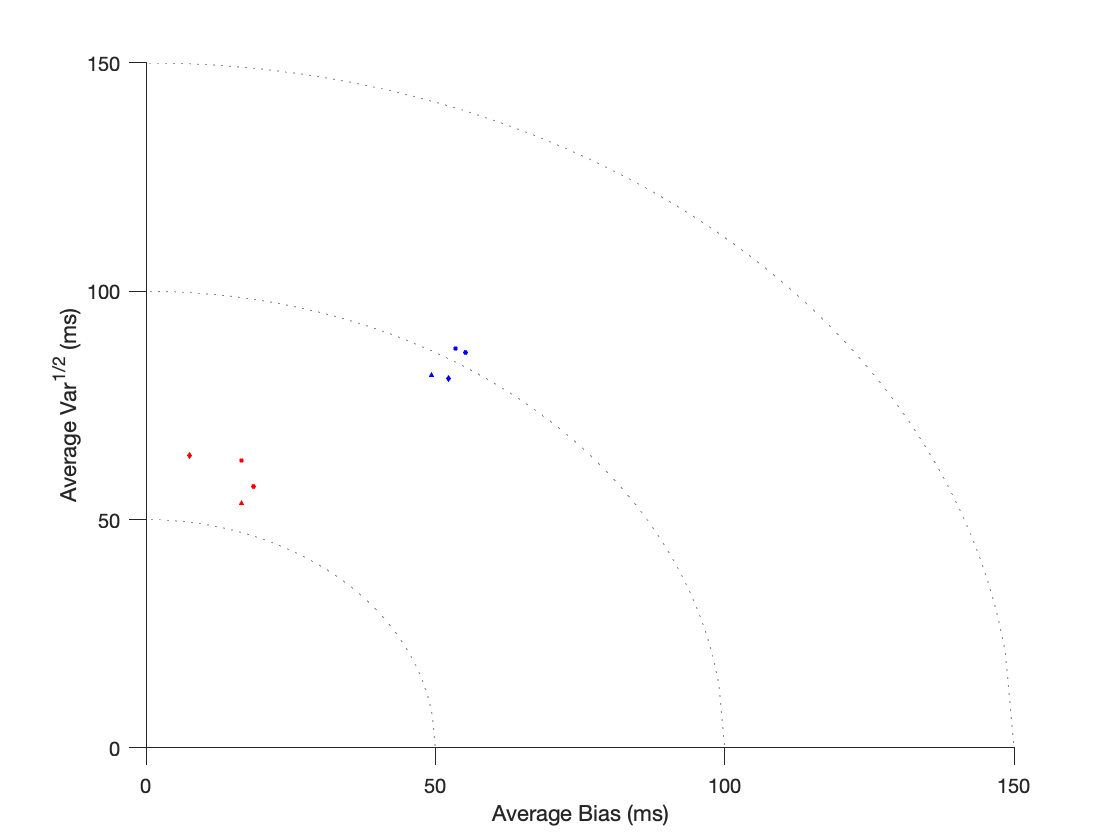

intercept: 3.475162e+02 (p=9.534122e-07), slope: 5.600147e-01 (p=1.114342e-07)


# trials: 3154


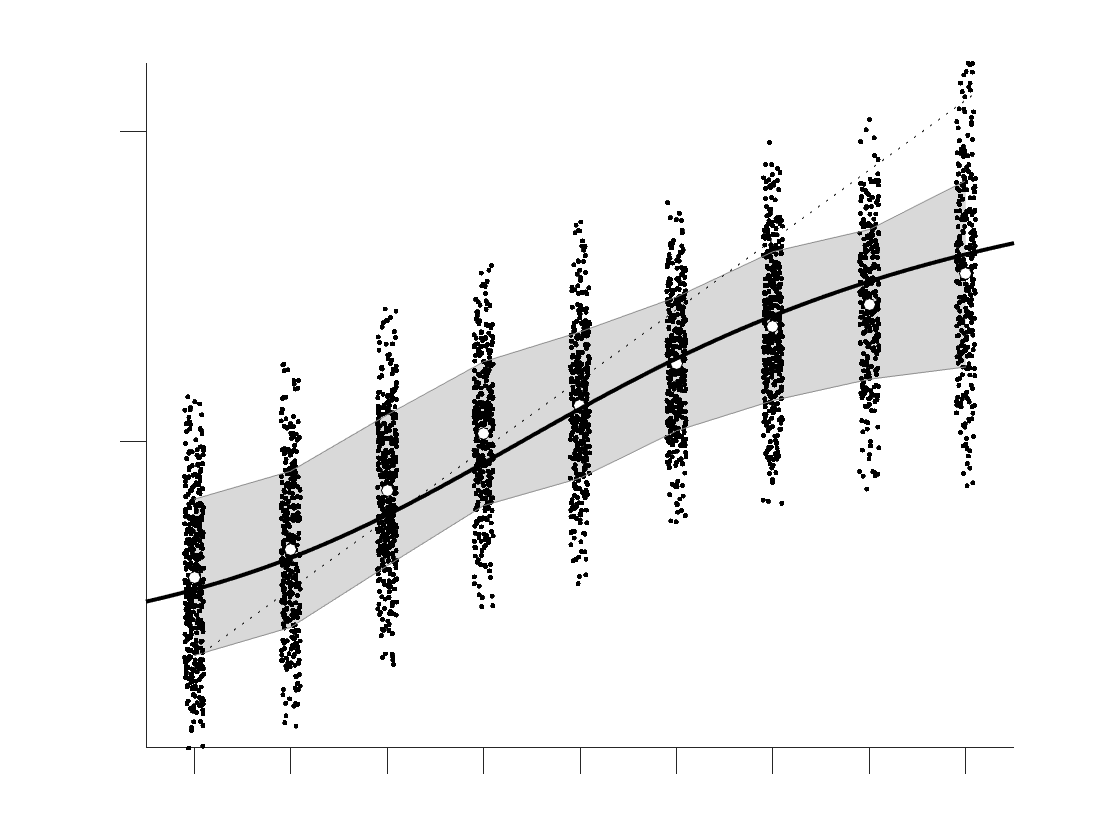

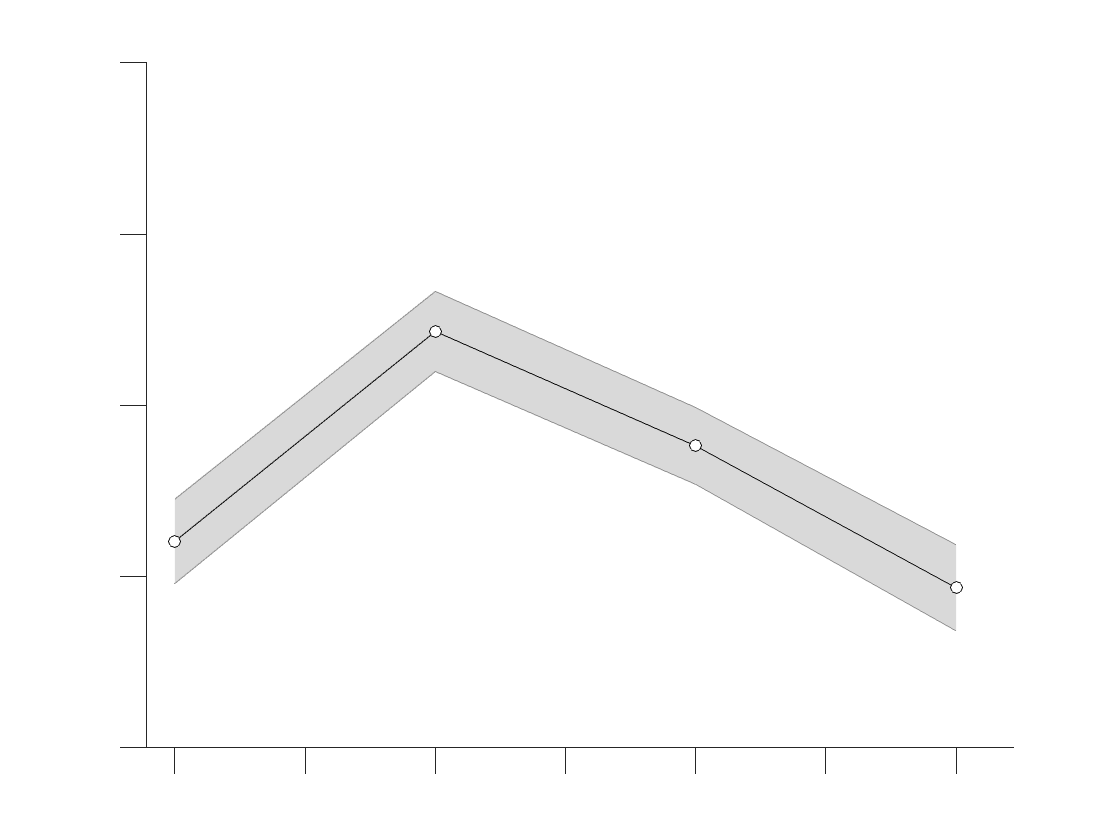

for i=1:nAnimal
    disp('=========');
    disp(animalNm{i});
    disp('=========');
    id=animalNm{i};
    tmp=load(fullfile(behDir,[ id '_RSGprior_DMFC.mat']));
    tmp.iAnimal=i;
    
    plot_S1A(S,tmp); % slope(short) vs slope(long): condition-specific
    
    plot_S1BC(S,tmp); % delta tp(extreme) vs delta tp (middle)+difference histogram: condition-specific
    
    plot_S1D(S,tmp); % bias vs variance
    
    plot_S1F(S,tmp); % generalization
    
    drawnow; pause(0.2);
end

### sub functions

function plot_S1F(S,tmp) % generalization

v2struct(S);
v2struct(tmp);

disp('FigS1F');
d=dir([animalNm{iAnimal} '*_RSGadapt.mat']);

% combine across sessions
tsMat=[];
tpMat=[];
cMat=[];
mutMat=[];
sdtMat=[];
ntMat=[];
sID=[];
dmutMat=[];

% to check variability across sessions for high contrast
%     hF=figure; setFigPos(2,3); ha;

for iS=length(d):(-1):1 % 1:length(d) % 2:2 % 1:length(d)
    
    load(d(iS).name); % t_s_all t_p_all idWide_all setFlashAlpha_all
    disp(d(iS).name);
    
    % G 2/19 has transition
    
    % remove first 1000 trials for G
    if iAnimal==nAnimal
        id=idWide_all==0 & t_p_all>0 & t_p_all<2*t_s_all & [1:length(idWide_all)]'>1000; % remove -tp
    else
        id=idWide_all==0 & t_p_all>0 & t_p_all<2*t_s_all; % remove -tp
    end
    ts=t_s_all(id); tsSet=unique(ts);
    tp=t_p_all(id);
    c=setFlashAlpha_all(id); cSet=unique(c); % 0.15 1
    idOut=false(size(ts));
    
    % session-specific plot
    tmpCmap=[0 0 0]; % [.5 .5 .5; 0 0 0];
    nSD=10;
        
    for iC=1:length(cSet)
        disp(cSet(iC));
        % remove outlier for each contrast/ts
        for iTs=1:length(tsSet)
            disp(tsSet(iTs));
            tmpId=(ts==tsSet(iTs)) & c==cSet(iC);
            
            % fit
            if cSet(iC)~=1 & iAnimal==2 % low contrast, two GM
                tpTmp=tp(tmpId);
                
                try
                    nGM=2;
                    GM=fitgmdist(tpTmp,nGM);
                    idClust=cluster(GM,tpTmp);
                    idClustFull=zeros(size(idOut)); idClustFull(tmpId)=idClust;
                    if nnz(idClust==1)>nnz(idClust==2) %  GM.mu(1)>GM.mu(2) % clust2 is outlier
                        idOut(idClustFull==2)=true;
                    else % clust1 is outlier
                        idOut(idClustFull==1)=true;
                    end
                    
                catch
                    nSD=0;rangeOut=[0 3];
                    [dTmp,idOutTmp,pout]=removeOutlier(tp(tmpId),nSD,rangeOut*tsSet(iTs));
                    idOut(tmpId)=~idOutTmp;
                    disp(['% outlier: ' num2str(mean(~idOutTmp)*100)]);
                    
                end
                
            else %H  high contrast,  uniform-Gaussian mixture
                nSD=0;rangeOut=[0 2];
                [dTmp,idOutTmp,pout]=removeOutlier(tp(tmpId),nSD,rangeOut*tsSet(iTs));
                idOut(tmpId)=~idOutTmp;
                disp(['% outlier: ' num2str(mean(~idOutTmp)*100)]);
            end
        end % ts
        
    end % for iC=1:length(unique(c))
    
    [mutTmp,~,~]=plotTpTs(ts(~idOut & c==cSet(1)),tp(~idOut & c==cSet(1)),0);
    
    % combine data across sessions
    tsMat=[tsMat(:); ts(~idOut)];
    tpMat=[tpMat(:); tp(~idOut)];
    cMat=[cMat(:); c(~idOut)];
    sID=[sID(:); iS*ones(nnz(~idOut),1)];
end % session

% plot pooled across sessions
h=figure; ha;
for iC=1:length(cSet)
    nSD=10;
    [mut,sdt,nt]=plotTpTs(tsMat(cMat==cSet(iC)),tpMat(cMat==cSet(iC)),1,tmpCmap(iC,:),h,'o',nSD); % 3rd for idplot
    mutMat=[mutMat mut(:)];
    sdtMat=[sdtMat sdt(:)]; % [5ts x low/high]
    ntMat=[ntMat nt(:)];
end % for iC=1:length(unique(c))

% fit BLS
if ~exist('wFit')
    [wFit,bic]=estWmWpOld(tpMat,tsMat,ones(size(tsMat)),'mmse1Wm');
    save('G_20190322_RSGadapt.mat','wFit','-append');
else
    plot(600:1200,BLS(600:1200,wFit.w_m,[min(tsMat) max(tsMat)],'uniform')+wFit.offset,'k-','linewidth',2);
    clear wFit;
end
disp(['# trials: ' num2str(length(tsMat))]);
xlim([min(tsMat)-unique(diff(unique(tsMat)))/2 max(tsMat)+unique(diff(unique(tsMat)))/2]);
set(gca,'xtick',unique(tsMat),'tickdir','out','ytick',600:200:1200,'ticklength',[0.03 0.03]); % 660 750 840 930 1020
remLabel;

idOdd=1:2:(size(mutMat,1)-1);
idEven=2:2:size(mutMat,1);

% get SE of mean difference
SEMD=sqrt(sum(([sdtMat(idOdd) sdtMat(idEven)].^2)./[ntMat(idOdd) ntMat(idEven)],2)); % [5ts x 1]

% plot deltaTp<low-high
hF2=figure; setFigPos(iAnimal,5);  ha;
tmpX=unique(tsMat);
shadedErrorBar(tmpX(idOdd),mutMat(idEven)-mutMat(idOdd),SEMD,{'ko-','markerfacecolor','w'});
%     shadedErrorBar(unique(tsMat),mutMat(:,1)-mutMat(:,2),SEMD,{'ko-','markerfacecolor','w'});
if iAnimal==1
    ylim([19 57]);
else
    ylim([0 60]);
end
set(gca,'xtick',unique(tsMat),'tickdir','out','ytick',0:15:60,'ticklength',[0.03 0.03]); % 660 750 840 930 1020
remLabel;

end

function plot_S1A(S,tmp) % slope(short) vs slope(long): condition-specific

v2struct(S);
v2struct(tmp);

sessUni=unique(sessId);
slope=nan(nPr,nEH,length(sessUni));
sFull=nan(nPr,nEH,nTarg,length(sessUni)); % for all comb (pr, EH, targ)
for iSess=1:length(sessUni)
    % session data
    idSess=sessId==sessUni(iSess);
    ts=T(~idOut & idSess);
    tp=t(~idOut & idSess);
    ctidx=2-idShortTrial(~idOut & idSess); % 1 for short, 2 for long
    citdx2=2-idHandEye(~idOut & idSess); % 1 for eye, 2 for hand
    citdx3=2-(theta(~idOut & idSess)==0); % 1 for right, 2 for left
    
    % weighted regression with precision of tp as weights
    % getting std(tp|ts)
    stp=nan(size(ts));
    stp2=nan(size(ts));
    for i=1:nPr
        for k=1:nTspp
            for j=1:nEH
                id=ctidx==i &... % idShortTrial
                    ts==Tmat{i}(k) &... % ts
                    citdx2==j;            % eye hand
                stp(id)=std(tp(id));
                for l=1:nTarg
                    id2=ctidx==i &... % idShortTrial
                        ts==Tmat{i}(k) &... % ts
                        citdx2==j &...            % eye hand
                        citdx3==l; % right left
                    stp2(id2)=std(tp(id2));
                end
            end
        end
    end
    for i=1:nPr
        for j=1:nEH
            id=ctidx==i &... % idShortTrial
                citdx2==j;            % eye hand
            LM=fitlm(ts(id),tp(id),'linear',...
                'Weights',1./stp(id));
            slope(i,j,iSess)=table2array(LM.Coefficients(2,1));
            %             disp(slope(i,j,iSess)); % debug
            %             figure; plot(ts(id),tp(id),'o'); ha; plot(ts(id),predict(LM),'-'); waitforbuttonpress; close;
            for l=1:nTarg
                id2=ctidx==i &... % idShortTrial
                    citdx2==j &...            % eye hand
                    citdx3==l; % right left
                LM2=fitlm(ts(id2),tp(id2),'linear',...
                    'Weights',1./stp2(id2));
                sFull(i,j,l,iSess)=table2array(LM2.Coefficients(2,1));
                %                 disp(sFull(i,j,k,l,iSess)); % debug
                %                 figure; plot(ts(id),tp(id),'o'); ha; plot(ts(id),predict(LM),'-'); waitforbuttonpress; close;
            end % l targ
        end % j EH
    end % i Pr
    
end

% new supplementary figure 1 (distribution of slope)
tmpMarker={'s','d';'o','^'};
cmapTmp=[0 .6 0;1 .5 0;0 0 1;1 0 0];

nBin=8;barWidth=0.4;markersize=4;
optsExpFig.Width=3; % 10/2.54;
optsExpFig.Height=3; % 7.3/2.54;

sS=squeeze(sFull(1,:,:,:));
sL=squeeze(sFull(2,:,:,:));

disp('FigS1A');
figure; ha;
icmap=1;
for iEH=1:nEH
    for iRL=1:nTarg
        x=sS(iEH,iRL,:);        y=sL(iEH,iRL,:);
        
        plot(x(:),y(:),['k' tmpMarker{iEH,iRL}],'markerfacecolor','w','markersize',markersize,'color',cmapTmp(icmap,:));
        axis([-0.1 1.2 -0.1 1.2]);
        plotIdentity(gca);  % plotVertical(gca,0,[]); plotVertical(gca,1,[]);plotHorizon(gca,0,[]); plotHorizon(gca,1,[]);
        set(gca,'xtick',0:0.25:1,'ytick',0:0.25:1,'tickdir','out','ticklength',[0.02 0.02]); remTickLabel;
        pause(0.1);
        % applytofig(gcf,optsExpFig);
        icmap=icmap+1;
    end % for iRL=1:nTarg
end % for iEH=1:nEH
drawnow; pause(0.2);
end

function plot_S1BC(S,tmp) % delta tp(extreme) vs delta tp (middle)+difference histogram: condition-specific

v2struct(S);
v2struct(tmp);

idChkModel= 0; % 1;
idUseOp=1;
sidUni=unique(sessId); % 170823
nSess=length(sidUni);

tmpMarker=fliplr({'^','o','d','s'}); % {'^','o','d','s'}; % ER>EL>HR>HL
cmapTmp=[0 .6 0;1 .5 0;0 0 1;1 0 0];
markersize=2; % 4;

dTp=nan(nSess,nPr,nEH,nTarg,2); % last for mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2)
nTp=nan(nSess,nPr,nEH,nTarg); % last for mean(ts2-ts1,ts5-ts4) vs mean(ts4-ts3,ts3-ts2)
cid=nan(nSess,nPr,nEH,nTarg); % 12345678 pr>EH>RL

RMSE=nan(nSess,nPr,nEH,nTarg,2); % BLS linear
vTp=nan(nSess,nPr,nEH,nTarg,nTspp);
mTp=nan(nSess,nPr,nEH,nTarg,nTspp);
resLM=nan(nSess,nPr,nEH,nTarg,nTspp);

if idUseOp
    minOp=0; % 0.8; % 9; % linearly scaled by white and original color (max#trials>original; min#trial>c+(1-c)*0.9
else
    minMS=1; % min marker size
    maxMS=10; % max marker size
end

for iS=length(sidUni):(-1):1 % 1:length(sidUni)
    %     disp(['===== ' num2str(sidUni(iS)) ' =====']);
    idS=sessId==sidUni(iS);
    
    for i=1:nPr % 1 short 2 long
        for j=1:nEH
            for l=1:nTarg
                
                id=idShortTrial==(2-i) &... % idShortTrial
                    idHandEye==(2-j) &...            % eye hand
                    theta==180*(l-1) &... % right left
                    idS &... % session
                    ~idOut; % outlier
                
                % get mean tp for each ts
                muTp=nan(length(Tmat{i}),1);
                varTp=nan(length(Tmat{i}),1);
                for k=1:length(Tmat{i})
                    tmpId=id & T==Tmat{i}(k);
                    muTp(k)=mean(t(tmpId));
                    varTp(k)=std(t(tmpId));
                end
                
                % model-based comparison b/t linear & BLS
                wFitTmp=wFitSessCond(iS,j,l);
                nParam=0; % 2;
                % no fitting
                sqErr=@(p,q) sum((muTp(:)-(BLS(q,p(1),[min(q) max(q)],'uniform')+p(2))).^2); % p: wm, offset, ts
                SE0=sqErr([wFitTmp.w_m,wFitTmp.(['offset' num2str(3-i)])],Tmat{i}(:));
                
                RMSE(iS,i,j,l,1)=sqrt(SE0/(length(Tmat{i})-nParam)); % SE>RMSE (N.B. now taking into account degree of freedom)
                LM=fitlm(Tmat{i},muTp,'linear');
                resLM(iS,i,j,l,:)=table2array(LM.Residuals(:,1));
                RMSE(iS,i,j,l,2)=sqrt(mean((muTp-LM.predict).^2)); % LM.RMSE; N.B. LinearModel's RMSE taking into account degree of freedom
                
                % check var(tp|extreme ts)< E(var(tp|priorMean))
                mTp(iS,i,j,l,:)=muTp;
                vTp(iS,i,j,l,:)=varTp;
                
                dTp(iS,i,j,l,1)=mean(diff(muTp(2:4)));
                dTp(iS,i,j,l,2)=mean([diff(muTp(1:2)) diff(muTp(4:5))]);
                nTp(iS,i,j,l)=nnz(id);
                cid(iS,i,j,l)=l+(j-1)*nTarg+(i-1)*nEH*nTarg;
                
            end % l targ
        end % j EH
    end % i pr
end % sess

nTp0=nTp; nTp=nTp(:); tmpMS=(nTp-min(nTp))/(max(nTp)-min(nTp)); % [0 1]
cid=cid(:);
disp(['# trials: ' num2str(max(nTp)) ', ' num2str(min(nTp))]);

disp('FigS1B');

figure; ha;  % scatter plot for model free

tmpX=dTp(:,:,:,:,1); tmpX=tmpX(:);
tmpY=dTp(:,:,:,:,2); tmpY=tmpY(:);

for i=1:length(nTp)
    if idUseOp
        % condition<prior-specific marker; red for short, blue for long
        idShortTmp=cid(i)<=(nEH*nTarg); % 1 for short, 0 for long
        cidTmp=cid(i)-(1-idShortTmp)*nEH*nTarg; % 1234 for ER EL HR HL
        tmpC=cmapTmp(cidTmp,:);
        tmpC=tmpC+(1-tmpC)*minOp*(1-tmpMS(i));
        plot(tmpX(i),tmpY(i),tmpMarker{cidTmp},... % fliplr({'^','o','d','s'});
            'color',tmpC,'markersize',markersize,'linewidth',0.5);
    else % idUseOp
        plot(tmpX(i),tmpY(i),'ko','markersize',tmpMS(i)*(maxMS-minMS)+minMS);
    end
end
axis tight;
xlim([20 125]);ylim([20 125]); set(gca,'xtick',30:30:120,'ytick',30:30:120,'tickdir','out');
plotIdentity(gca);
ylabel('difference in mean t_p for boundary t_s');
xlabel('difference in mean t_p for middle t_s');
remTickLabel;remLabel;
% applytofig(gcf,optsExpFig);
drawnow; pause(0.2);

% [p,h]=signrank(tmpX,tmpY); disp(['sigmoid: pooled across sessions,prior,effector,direction: ' num2str(p,3)]);
%
% % stat for each condition; pooled across prior
% for i=1:(length(unique(cid))/nPr)
%     idCondTmp=i==(mod(cid-1,4)+1); % 12341234
%     [p,h]=signrank(tmpX(idCondTmp),tmpY(idCondTmp)); disp(['cond' num2str(i) ': ' num2str(p,3)]);
% end

disp('FigS1C');

% histogram: now condition-specific<prior-specific
figure; ha;
nBin=15;barWidth=0.2;markersize=10;
xHist=linspace(min(tmpY-tmpX),max(tmpY-tmpX),nBin); % getting bin locations
idShortTmp=cid<=(nEH*nTarg); % 1 for short, 0 for long
% plot
diffXY=cell(nPr,1);
for i=1:(length(unique(cid))/nPr) % nPr
    idCondTmp=i==(mod(cid-1,4)+1); % 12341234
    diffXY{i}=-(tmpY(idCondTmp)-tmpX(idCondTmp));
    hHist=histogram(diffXY{i},xHist);
    Xval    = hHist.BinEdges + hHist.BinWidth*0.5 +hHist.BinWidth*(i-1)/(nEH*nTarg)+1/(nEH*nTarg*2); % (i-(nPr+1)/2)/2; % binWidth*0.25 for short, 0.75 for long
    Xval    = Xval(1:end-1);
    Yval    = hHist.Values;
    delete(hHist);
    
    tmpC=cmapTmp(i,:); % 1234 for ER EL HR HL
    hTmp      = bar(Xval,Yval,'BarWidth',barWidth,'FaceColor',tmpC,'EdgeColor','none'); %  pplot.cmap{2*i-1}
end
axis tight;
maxYlim=max(ylim);
% plot mean
for i=1:(length(unique(cid))/nPr) % nPr
    tmpC=cmapTmp(i,:); % 1234 for ER EL HR HL
    plot(mean(diffXY{i}),1.1*maxYlim,'color',tmpC,'markerfacecolor',tmpC,'marker','v','markersize',markersize); %  pplot.cmap{2*i-1}
end % for i=1:nPr
ylabel('# data sets');
xlabel('degree of being sigmoidal');
plotVertical(gca,0,[]);
set(gca,'tickdir','out','xtick',-60:30:60,'ytick',0:5:10); xlim([-80 80]);
remTickLabel;remLabel;
% applytofig(gcf,optsExpFig);
drawnow; pause(0.2);

end

function plot_S1D(S,tmp) % slope(short) vs slope(long): condition-specific

v2struct(S);
v2struct(tmp);

% simulation BLS nSim times and average them
nSim=500;
nRep=1; % 50 times more trials than data: now condition-specific, 1600 trials/40 cond: 40 trials/cond

% plot
lw=0.5;
ms=2;
tmpMarker={'s','d';'o','^'}; % eyeRight, eyeLeft; handRight, handLeft

%% main
iFig=1;

if iAnimal==1
    tmpMarker2='^';
else
    tmpMarker2='o';
end

disp('FigS1D');
h1=figure;  ha; % bias var

for j=1:nEH
    for k=1:nTarg
        %         disp([ehNm{j} targNm{k}]);
        
        wm=wFitCond(j,k).w_m;
        wp=wFitCond(j,k).w_p;
        bL=wFitCond(j,k).offset1;
        bS=wFitCond(j,k).offset2;
        
        %% simulation BLS nSim times and average them
        % do simulation & calculate mean/SD
        mutSim=nan(nPr,nTspp,nSim); % mean [2priors x 5ts/pr x #simulation]
        sdtSim=nan(nPr,nTspp,nSim); % SD  [2priors x 5ts/pr x #simulation]
        rmsBiasSim=nan(nPr,nSim); % mean Bias  [2priors x #simulation]
        rmsVSim=nan(nPr,nSim); % mean sqrtVar  [2priors x #simulation]
        
        slopeSim=nan(nPr,nSim);
        for iSim=1:nSim
            for i=1:nPr % for each prior
                tmpId= idHandEye==(2-j) & theta==180*(k-1) & idShortTrial==(2-i) & ~idOut; % sessId==iS(jS) &
                tmpT=repmat(T(tmpId),nRep,1);
                
                % simulation
                offset=bS*(2-i)+bL*(i-1);
                tm=tmpT+wm*randn(size(tmpT)).*tmpT;
                te=BayesEst(tm,wm,[min(tmpT) max(tmpT)],'uniform')+offset;
                tpModel=te+wp*randn(size(te)).*te;
                
                % calculate mean/SD
                sdtModel=nan(size(tmpT));
                tmpTlist=unique(tmpT);
                for jT=1:nnz(tmpTlist)
                    id=(tmpT==tmpTlist(jT));
                    
                    mutSim(i,jT,iSim)=mean(tpModel(id));
                    sdtSim(i,jT,iSim)=std(tpModel(id));
                    
                    sdtModel(id)=std(tpModel(id));
                end
                
                LM=fitlm(tmpT,tpModel,'linear',...
                    'Weights',1./sdtModel);
                slopeSim(i,iSim)=table2array(LM.Coefficients(2,1));
                
                % prior-specific meanBias & sqrtVar
                rmsBiasSim(i,iSim)=sqrt(mean((mutSim(i,:,iSim)-tmpTlist(:)').^2));
                rmsVSim(i,iSim)=sqrt(mean((sdtSim(i,:,iSim)).^2));
            end % for i=1:nPr
        end % for iSim=1:nSim
        
        %% calculate mean and SD for each ts
        mut=nan(nPr,nTspp); % mean [2priors x 5ts/pr]
        sdt=nan(nPr,nTspp); % SD
        rmsBias=nan(nPr,1); % mean Bias [2priors x 1]
        rmsV=nan(nPr,1); % mean sqrtVar
        for i=1:nPr
            for iTs=1:length(Tmat{i})
                
                tmpId=idHandEye==(2-j) & theta==180*(k-1) & idShortTrial==(2-i) & T==Tmat{i}(iTs)  & ~idOut; % sessId==iS(jS) &
                
                mut(i,iTs)=mean(t(tmpId));
                sdt(i,iTs)=std(t(tmpId));
                
            end % for iTs=1:length(Tmat{i})
            
            % prior-specific meanBias & sqrtVar
            rmsBias(i)=sqrt(mean((mut(i,:)-Tmat{i}(:)').^2));
            rmsV(i)=sqrt(mean((sdt(i,:)).^2));
        end % i pr
        
        %% plot
        
        for i=1:nPr
            x1=rmsBias(i); % data
            y1=rmsV(i);
            % choose best
            tmpE=sqrt(((rmsBiasSim(i,:)-x1).^2)+((rmsVSim(i,:)-y1).^2));
            iBest=min(tmpE)==tmpE;
            x2=rmsBiasSim(i,iBest); % mean(rmsBiasSim(i,:)); % model
            y2=rmsVSim(i,iBest); % mean(rmsVSim(i,:));
            
            figure(h1); % bias vs var
            %             plot([x1;x2],[y1;y2],'-','color',pplot.cmap{(i-1)*2+1},'linewidth',lw); % line %%%%%
            plot(x1,y1,tmpMarker{j,k},'color',pplot.cmap{(i-1)*2+1},'linewidth',lw,'markersize',ms,'markerfacecolor',pplot.cmap{(i-1)*2+1}); % data
            %             plot(x2,y2,tmpMarker{j,k},'color',pplot.cmap{(i-1)*2+1},'linewidth',lw,'markersize',ms,'markerfacecolor','w'); % model
            drawnow;
            
        end          % i pr
    end % for k=1:nTarg
end % for j=1:nEH

figure(h1); % bias vs var
% plot    circle
axis tight;
axis([0 150 0 150]);  % tight;
for i=50:50:150, plotCircleHalf(gca,i,0.5+[0 0 0]); end;
set(gca,'xtick',0:50:250,'ytick',0:50:250,'tickdir','out','ticklength',[0.02 0.02]); xlabel('Average Bias (ms)');ylabel('Average Var^1^/^2 (ms)'); % ylabel('$\sqrt{Var}$ (ms)','Interpreter','Latex');


end

function estimate = BayesEst(...
    measurements, ...
    weberMeasure, ...
    priorParams,  ...
    prior)
%% Using Matlab's integral() function

%measurements must be a column vector of the measurement values
%
%weberMeasure is the Weber fraction of the measurement. Pass in one value
%or a column vector with length equal to measurements.
%
%priorParams defines the distribution. For a uniform prior this is the just
%the support (start and end). For a Gaussian prior it's the mean and
%variance.
%
%prior is the prior type. Leave blank for uniform.

wm = weberMeasure;
if numel(wm) == 1
    wm = repmat(wm,size(measurements,1),1);
end

if ~exist('prior','var') || isempty(prior)
    prior = 'uniform';
end

switch prior
    case 'uniform'
        alpha = 1./integral(@(s)posteriorNum(s,measurements,wm), ...
            priorParams(1), priorParams(2),'ArrayValued',true);
        estimate = integral(@(s)alpha.*s.*posteriorNum(s,measurements,wm), ...
            priorParams(1), priorParams(2),'ArrayValued',true);
        
end


end


function numValue = posteriorNum(s,m,wm)
%% This is the simplest version of the calculation.
%Does not allow the measurements to covary.

sigmaDet = ((s*wm).^2).^size(m,2);
numValue = 1./sqrt(2*pi*sigmaDet).*exp(-.5*sum((s-m).^2./(s*wm).^2,2));

end

function plotCircleHalf(h,radius,color)
% assuming x ranging from negative to positive
x=linspace(0,radius,100);
y=sqrt((radius^2)-(x.^2));
plot(x,y,':','color',color); hold on;
end